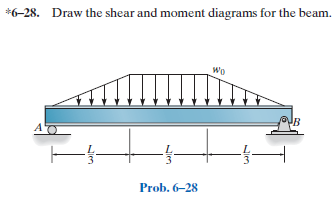

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-28P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-28P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# load data

x = sym('x');
wo = sym('wo');
L = sym('L', 'positive');
w1 = findpoly(1, 'thru', [0 0], 'thru', [L/3 -wo]);
w2(x) = -wo;
w3 = findpoly(1, 'thru', [2*L/3 -wo], 'thru', [L 0]);

# beam

b = beam; 
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rb', L);
b = b.add('distributed', 'force', w1, [0 L/3]);
b = b.add('distributed', 'force', w2, [L/3 2*L/3], [false true]);
b = b.add('distributed', 'force', w3, [2*L/3 L], [false true]);

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,x\,\left(110\,L^{4}-180\,L^{2}\,x^{2}+81\,x^{4}\right)}{3240\,\text{E}\,\text{I}\,L} & \text{ if }3\,x\leq L\\ -\frac{\mathrm{wo}\,\left(L^{4}+315\,L^{3}\,x+90\,L^{2}\,x^{2}-810\,L\,x^{3}+405\,x^{4}\right)}{9720\,\text{E}\,\text{I}} & \text{ if }L<3\,x\wedge 3\,x\leq 2\,L\\ -\frac{\mathrm{wo}\,\left(L-x\right)\,\left(11\,L^{4}+36\,L^{3}\,x+306\,L^{2}\,x^{2}-324\,L\,x^{3}+81\,x^{4}\right)}{3240\,\text{E}\,\text{I}\,L} & \text{ if }2\,L<3\,x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{\mathrm{wo}\,\left(22\,L^{4}-108\,L^{2}\,x^{2}+81\,x^{4}\right)}{648\,\text{E}\,\text{I}\,L} & \text{ if }3\,x\leq L\\ -\frac{\mathrm{wo}\,\left(L-2\,x\right)\,\left(7\,L^{2}+18\,L\,x-18\,x^{2}\right)}{216\,\text{E}\,\text{I}} & \text{ if }L<3\,x\wedge 3\,x\leq 2\,L\\ -\frac{\mathrm{wo}\,\left(5\,L^{4}+108\,L^{3}\,x-378\,L^{2}\,x^{2}+324\,L\,x^{3}-81\,x^{4}\right)}{648\,\text{E}\,\text{I}\,L} & \text{ if }2\,L<3\,x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{\mathrm{wo}\,x\,\left(2\,L^{2}-3\,x^{2}\right)}{6\,L} & \text{ if }3\,x\leq L\\ -\frac{\mathrm{wo}\,\left(L^{2}-27\,L\,x+27\,x^{2}\right)}{54} & \text{ if }L<3\,x\wedge 3\,x\leq 2\,L\\ -\frac{\mathrm{wo}\,\left(L-x\right)\,\left(L^{2}-6\,L\,x+3\,x^{2}\right)}{6\,L} & \text{ if }2\,L<3\,x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{\mathrm{wo}\,\left(2\,L^{2}-9\,x^{2}\right)}{6\,L} & \text{ if }3\,x\leq L\\ \frac{\mathrm{wo}\,\left(L-2\,x\right)}{2} & \text{ if }L<3\,x\wedge 3\,x\leq 2\,L\\ \frac{\mathrm{wo}\,\left(7\,L^{2}-18\,L\,x+9\,x^{2}\right)}{6\,L} & \text{ if }2\,L<3\,x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} -\frac{3\,\mathrm{wo}\,x}{L} & \text{ if }3\,x\leq L\\ -\mathrm{wo} & \text{ if }L<3\,x\wedge 3\,x\leq 2\,L\\ -\frac{3\,\mathrm{wo}\,\left(L-x\right)}{L} & \text{ if }2\,L<3\,x \end{array}\right.$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Ra} & \frac{L\,\mathrm{wo}}{3}\\ \mathrm{Rb} & \frac{L\,\mathrm{wo}}{3} \end{array}\right)$$

ha

 
ha =
 
Empty sym: 0-by-2
 


# shear and moment diagram

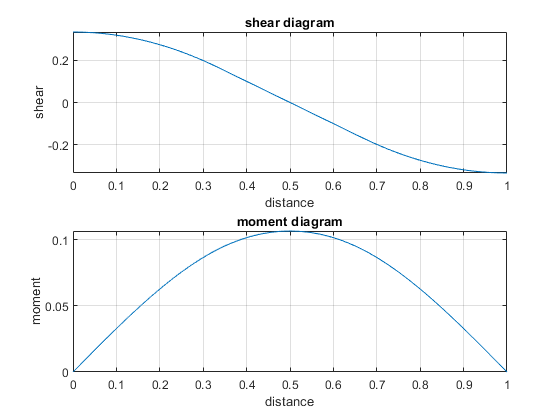

beam.shear_moment(m, v, [0 1], [wo L], 1);

# clean up

addvar(y);
new_assum = assumptions;